# Hough Transformation

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2020-12-20

### **Mapping Points into the Parameter Space**

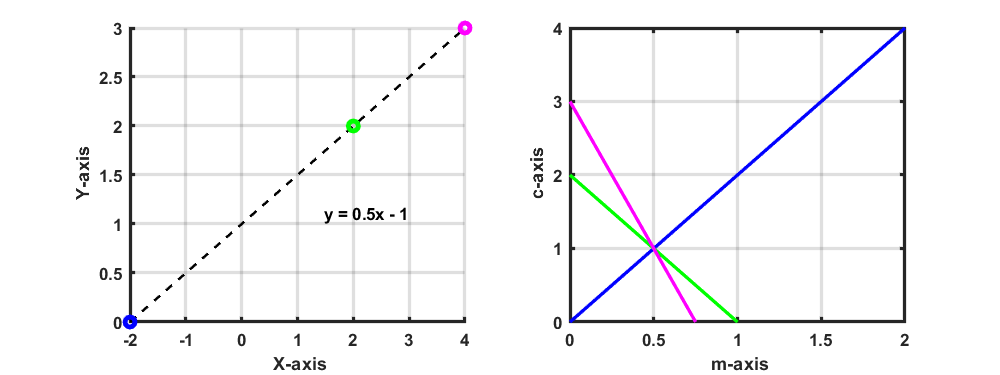

close all; clc; clear;

% line equation: y = 2x + 1;
m = 0.5;
b = 1;


pts = [-2 0; 2  2; 4 3];

h = figure(1); set(h, 'Position', [100, 100, 800, 300]);

subplot(121);

endPt_x = [min(pts(:,1)) max(pts(:,1))];
endPt_y = [min(pts(:,2)) max(pts(:,2))];

line(endPt_x, endPt_y,  'linewidth', 1.5, 'Color', 'k', 'lineStyle', '--');hold on;

text(endPt_x(2)-1, endPt_y(1)+1, sprintf('y = %sx - %s', num2str(m), num2str(b)),'horiz','right','vert','bottom','FontWeight','bold');

plot(pts(1,1), pts(1,2), 'ob', 'linewidth', 3);
plot(pts(2,1), pts(2,2), 'og', 'linewidth', 3);
plot(pts(3,1), pts(3,2), 'om', 'linewidth', 3);

axis tight; grid on; hold off
xlabel('\bf X-axis');xlim(endPt_x);
ylabel('\bf Y-axis');ylim(endPt_y);
set(gca,'xtick',-5:5); 
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold');

subplot(122);

mr = 0:0.1:2;

c1 = -pts(1,1)*mr + pts(1,2);
c2 = -pts(2,1)*mr + pts(2,2);
c3 = -pts(3,1)*mr + pts(3,2);

plot(mr, c1, '-b', 'linewidth', 2); hold on;
plot(mr, c2, '-g', 'linewidth', 2);
plot(mr, c3, '-m', 'linewidth', 2);

axis tight; grid on; hold off
xlabel('\bf m-axis');xlim([0 2]);
ylabel('\bf c-axis');ylim([0 4])
set(gca,'xtick',0:0.5:2); 
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold');

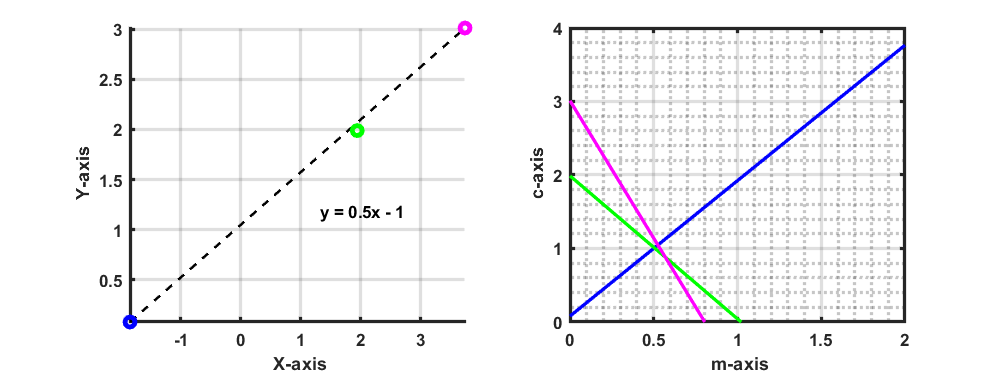



h = figure(2); set(h, 'Position', [100, 100, 800, 300]);

subplot(121);

rng(29);

pts = pts + randn(3,2)*0.1;

endPt_x = [min(pts(:,1)) max(pts(:,1))];
endPt_y = [min(pts(:,2)) max(pts(:,2))];

line(endPt_x, endPt_y,  'linewidth', 1.5, 'Color', 'k', 'lineStyle', '--');hold on;

text(endPt_x(2)-1, endPt_y(1)+1, sprintf('y = %sx - %s', num2str(m), num2str(b)),'horiz','right','vert','bottom','FontWeight','bold');

plot(pts(1,1), pts(1,2), 'ob', 'linewidth', 3);
plot(pts(2,1), pts(2,2), 'og', 'linewidth', 3);
plot(pts(3,1), pts(3,2), 'om', 'linewidth', 3);

axis tight; grid on; hold off
xlabel('\bf X-axis');xlim(endPt_x);
ylabel('\bf Y-axis');ylim(endPt_y)
set(gca,'xtick',-5:5); 
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold');

subplot(122);

m = 0:0.1:2;

c1 = -pts(1,1)*m + pts(1,2);
c2 = -pts(2,1)*m + pts(2,2);
c3 = -pts(3,1)*m + pts(3,2);

plot(m, c1, '-b', 'linewidth', 2); hold on;
plot(m, c2, '-g', 'linewidth', 2);
plot(m, c3, '-m', 'linewidth', 2);

axis tight; grid on; hold off
xlabel('\bf m-axis');xlim( [0 2]);
ylabel('\bf c-axis');ylim([0 4])
set(gca,'xtick',0:0.5:2); 
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold'); grid minor;

### Hough Transformation Principle (Example)

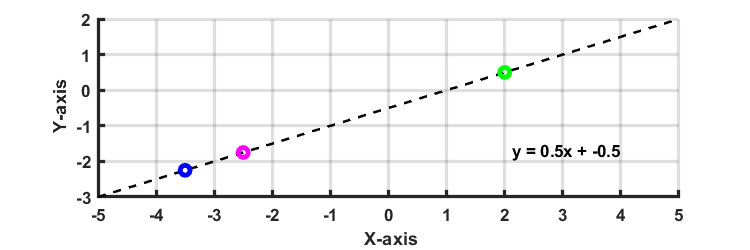

close all; clc; clear;

rng(12);

% line equation: y = 0.5x - 0.5;
m = 0.5;
b = -0.5;

x_range = -5:0.5:5;
x_idx = randperm(numel(x_range),3);

dataPt_x = x_range(x_idx);
dataPt_y = m*dataPt_x + b; 

h = figure(1);
set(h, 'Position', [100, 100, 600, 200]);

endPt_x = [min(x_range) max(x_range)];
endPt_y = m*endPt_x + b;
line(endPt_x, endPt_y,  'linewidth', 1.5, 'Color', 'k', 'lineStyle', '--');hold on;

text(endPt_x(2)-1, endPt_y(1)+1, sprintf('y = %sx + %s', num2str(m), num2str(b)),'horiz','right','vert','bottom','FontWeight','bold');

plot(dataPt_x(1), dataPt_y(1), 'ob', 'linewidth', 3);
plot(dataPt_x(2), dataPt_y(2), 'og', 'linewidth', 3);
plot(dataPt_x(3), dataPt_y(3), 'om', 'linewidth', 3);

axis tight; grid on; hold off
xlabel('\bf X-axis');xlim(endPt_x)
ylabel('\bf Y-axis');ylim(endPt_y)
set(gca,'xtick',endPt_x(1):1:endPt_x(2))
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold')

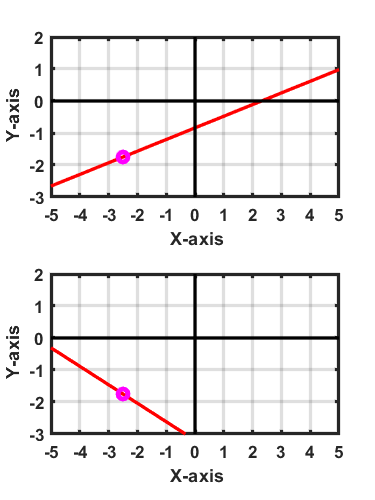


theta_axis = -90:0.5:89;

% dataPt_x(3), dataPt_y(3)
h = figure(2);
set(h, 'Position', [100, 100, 300, 400]);

theta2_sp = [-70 60];
rho2_sp = dataPt_x(3)*cosd(theta2_sp)+dataPt_y(3)*sind(theta2_sp);

x_sample = -5:0.1:5;
y1_sample = -cosd(theta2_sp(1))/sind(theta2_sp(1))*x_sample + rho2_sp(1)/sind(theta2_sp(1));
y2_sample = -cosd(theta2_sp(2))/sind(theta2_sp(2))*x_sample + rho2_sp(2)/sind(theta2_sp(2));

subplot(211); plot(x_sample, y1_sample, '-r', 'linewidth', 2); hold on;
plot(dataPt_x(3), dataPt_y(3), 'om', 'linewidth', 3);
line([min(endPt_x) max(endPt_x)], [0 0], 'color', 'k', 'linewidth', 2);
line([0 0], [min(endPt_x) max(endPt_x)], 'color',  'k', 'linewidth', 2);

axis tight; grid on; hold off
xlabel('\bf X-axis');xlim(endPt_x)
ylabel('\bf Y-axis');ylim(endPt_y)
set(gca,'xtick',endPt_x(1):1:endPt_x(2))
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold')

subplot(212); plot(x_sample, y2_sample, '-r', 'linewidth', 2); hold on;
plot(dataPt_x(3), dataPt_y(3), 'om', 'linewidth', 3);
line([min(endPt_x) max(endPt_x)], [0 0], 'color', 'k', 'linewidth', 2);
line([0 0], [min(endPt_x) max(endPt_x)], 'color',  'k', 'linewidth', 2);

axis tight; grid on; hold off
xlabel('\bf X-axis');xlim(endPt_x)
ylabel('\bf Y-axis');ylim(endPt_y)
set(gca,'xtick',endPt_x(1):1:endPt_x(2))
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold')

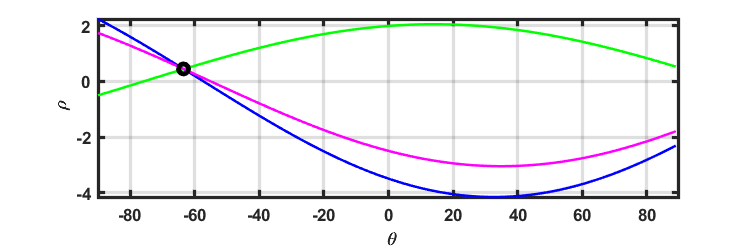



h = figure(3);
set(h, 'Position', [100, 100, 600, 200]);

rho1 = dataPt_x(1)*cosd(theta_axis)+dataPt_y(1)*sind(theta_axis);
plot(theta_axis, rho1, 'b', 'linewidth', 1.5); hold on;

rho2 = dataPt_x(2)*cosd(theta_axis)+dataPt_y(2)*sind(theta_axis);
plot(theta_axis, rho2, 'g', 'linewidth', 1.5); 

rho3 = dataPt_x(3)*cosd(theta_axis)+dataPt_y(3)*sind(theta_axis);
plot(theta_axis, rho3, 'm', 'linewidth', 1.5); 

dist_lines = abs(rho1-rho2) + abs(rho2-rho3) + abs(rho1-rho3);
[~,idx] = min(dist_lines);

plot(theta_axis(idx), rho1(idx), 'ok', 'linewidth', 3);

grid on; hold off; 
xlabel('\bf \theta');xlim([-90 90]);
ylabel('\bf \rho');
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold')


etheta = theta_axis(idx);
erho = rho1(idx);
% y = -cos(etheta)/sin(etheta)*x + erho/sin(etheta);
fprintf('Estimated line equation: y = %1.3f * x + %1.3f', ...
    -1*cosd(etheta)/sind(etheta), erho/sind(etheta));

Estimated line equation: y = 0.499 * x + -0.505

### Hough Transformation

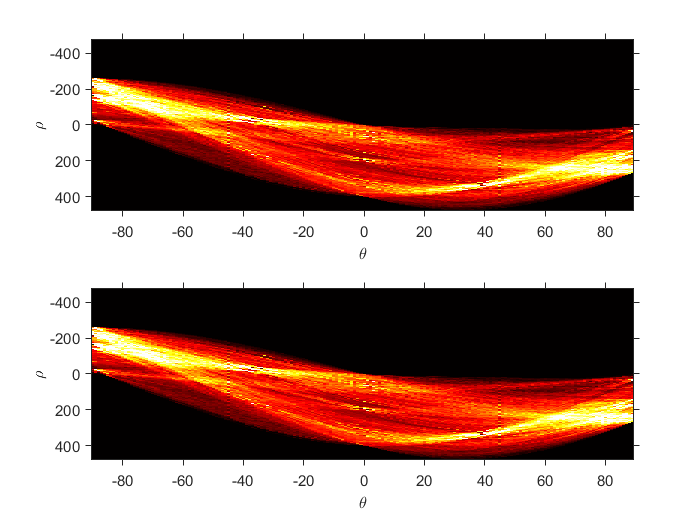

clear; close all; clc;
img = imread('gantrycrane.png');
img = rgb2gray(img);
BW = edge(img, 'canny');

imsz = size(img);

rho_res = 1;
theta_axis = -90:1:89;
 
[row,col] = find(BW==1);
img_diag = round(hypot(imsz(1)-1, imsz(2)-1));
rho_axis = -img_diag:rho_res:img_diag;

rho= (col-1)*cosd(theta_axis) + (row-1)*sind(theta_axis);

X = zeros(numel(rho_axis), numel(theta_axis));
for ii=1:numel(col)
    C = abs(bsxfun(@minus, rho(ii,:), rho_axis'));
    [~,ind_rho] = min(C);
    idx = sub2ind(size(X), ind_rho, 1:numel(theta_axis));
    X(idx) = X(idx) + 1;
end

figure(1); % both are the same
subplot(211); imshow(imadjust(rescale(X)),'Xdata', theta_axis, 'YData', rho_axis,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, colormap(gca,hot);

[H,T,R] = hough(BW); % use of hough function
subplot(212); imshow(imadjust(rescale(H)),[],'XData',T,'YData',R,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, colormap(gca,hot);

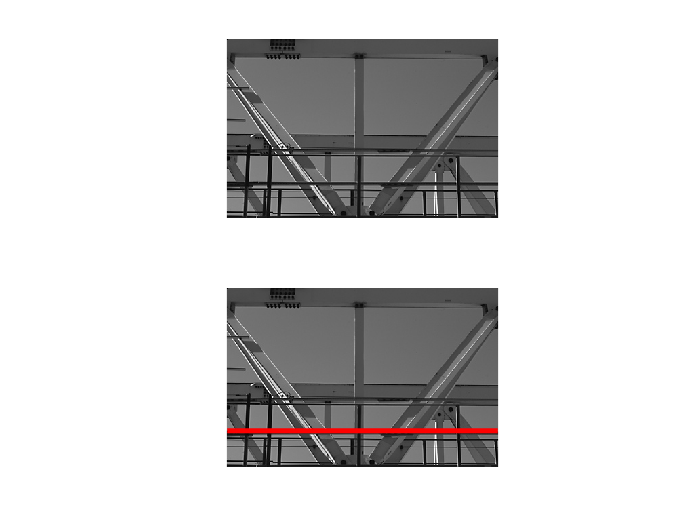


p = houghpeaks(H,1);

d = R(p(1));
theta = T(p(2));

x = 1:size(img,2);
y = 1/sind(theta)*(d-x*cosd(theta));

figure(2);
subplot(211); imshow(img);
subplot(212); imshow(img); hold on; plot(x, y,'r', 'linewidth', 3); hold off